# PSET 5

## Tarun Kamath

## Part 1: Time Series Analysis and Periodogram

- We are sampling at 1 kHz, thus there is 1000 samples every 1 second. Thus our sampling interval is .001 seconds. There are 5000 recordings, thus we are sampling for 5 seconds.

- We can plot the data below:

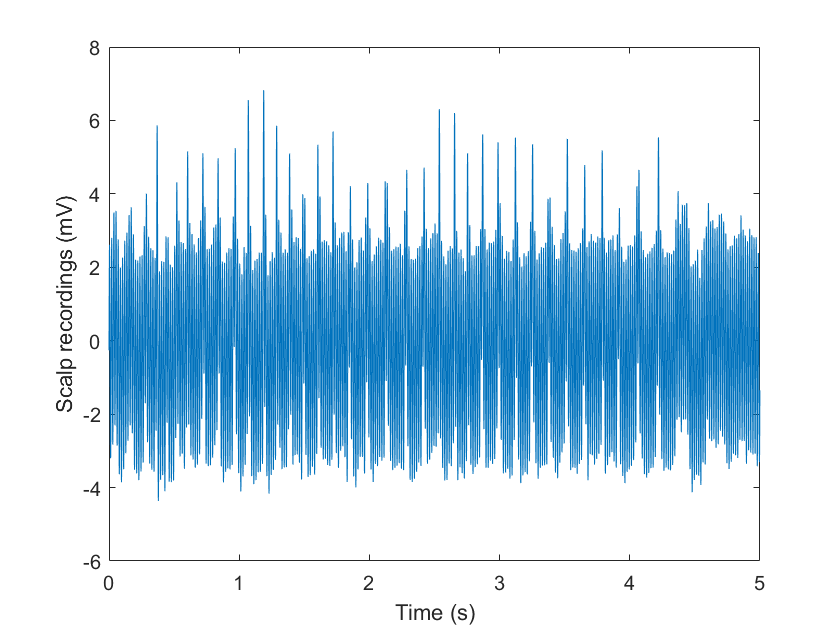

load('EEGepilepsy.mat'); %Load the data
time = 0:.001:4.999; 
plot(time,epileptic); %Plot the data
xlabel("Time (s)");
ylabel("Scalp recordings (mV)");

It seems as though the activity is extremely clustered together and that there may be some rhythmic activity.

3. We plot the autocorrelation below:

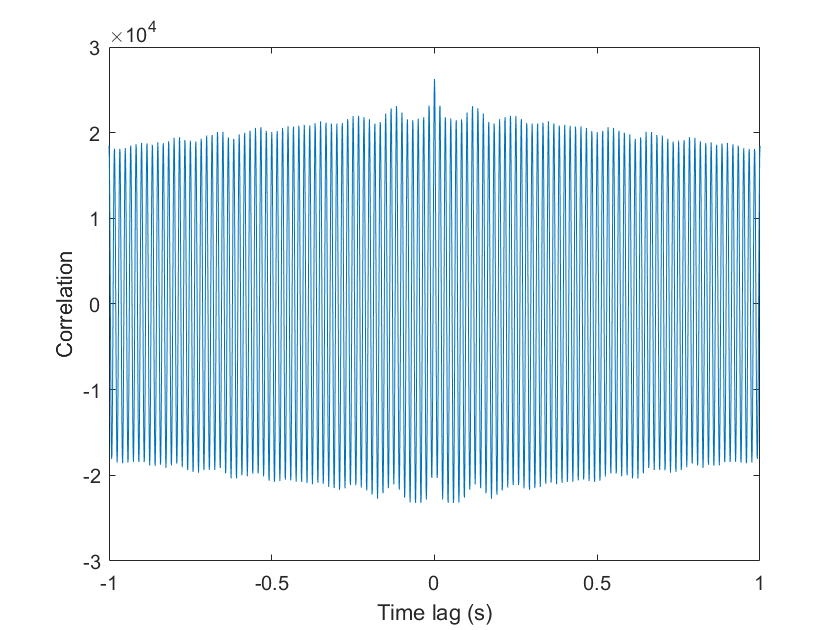

t = -4.999:.001:4.999; %Correlation between positive and negative times
autocorrelation = xcorr(epileptic);
plot(t,autocorrelation);
xlabel('Time lag (s)');
ylabel('Correlation');
xlim([-1 1]);

From this we see that there seem to be small periodic variations in the autocorrelation of the signal every 10 ms or so. This would imply the signal is periodic on the order of 10 ms.

4. Here is the periodogram of the signal:

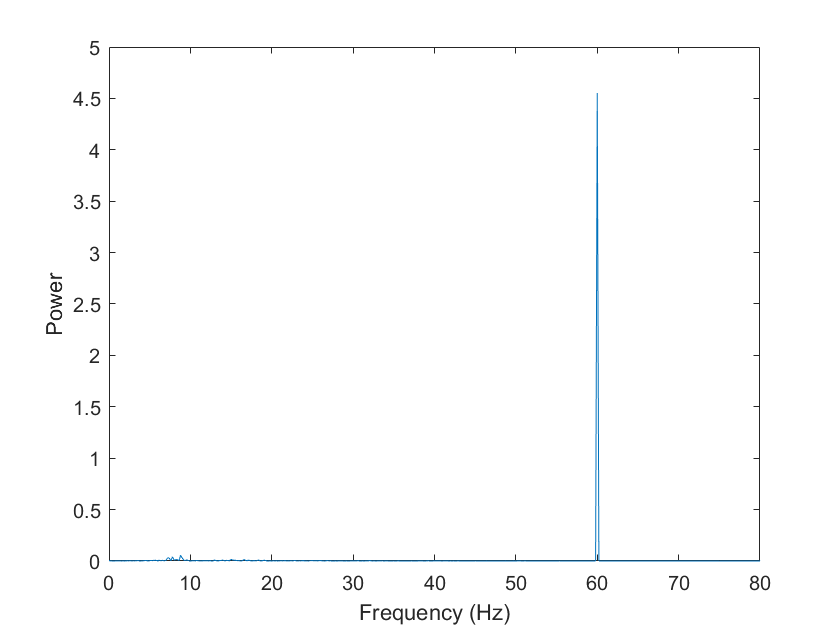

eplength = length(epileptic);
freqstep = 1000/eplength;
freqvec = freqstep*[-(eplength/2):(eplength/2)-1]; %Vector of frequencies
shiftedsignal =circshift(epileptic,[0,eplength/2]);%Shift our signal       
fftep =fft(shiftedsignal, eplength)/eplength; %Find FFT and normalize to length          
FFTEP =circshift(fftep,[0,eplength/2]); %Shift the FFT back          
power = 2*abs(FFTEP).^2; %Take the power
plot(freqvec,power);
xlabel('Frequency (Hz)');
xlim([0 80]);
ylabel(['Power']);

5. So the maximum frequency that we have in our signal is 80 Hz, thus our Nyquist frequency must be at least twice our greatest frequency. Thus our Nyquist frequency is **500 Hz**. The frequency resolution on the periodogram is **.02 Hz.**

6. We show the replotting of this below

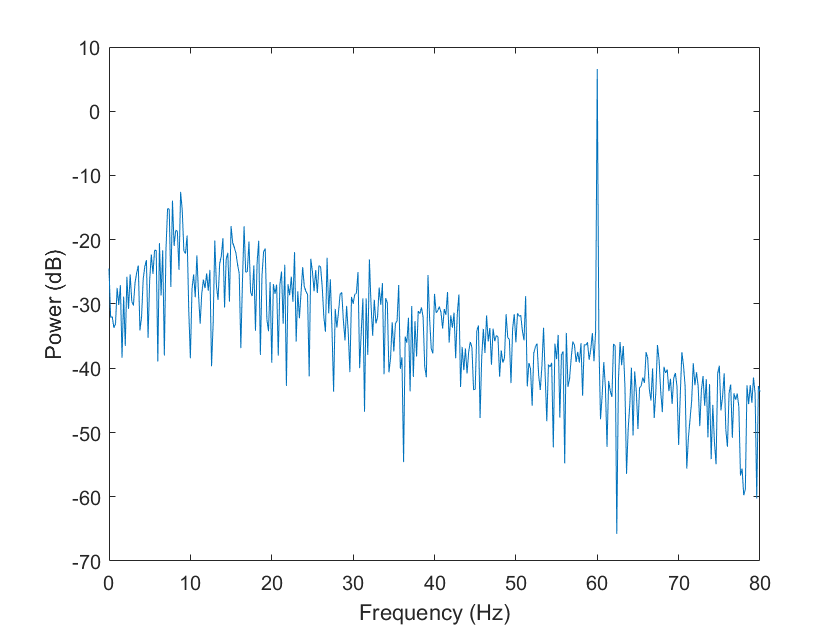

decibelpower = 10*log10(power); %Decibel is a log scale
plot(freqvec, decibelpower);
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power (dB)');

Here it seems as though there are two major frequencies at 60 Hz and at around 10 Hz. 

7. Now we can put the x axis on a logarithmic scale as well:

semilogx(freqvec, decibelpower); %Taking a log scale of frequency too
xlim([0 80]);

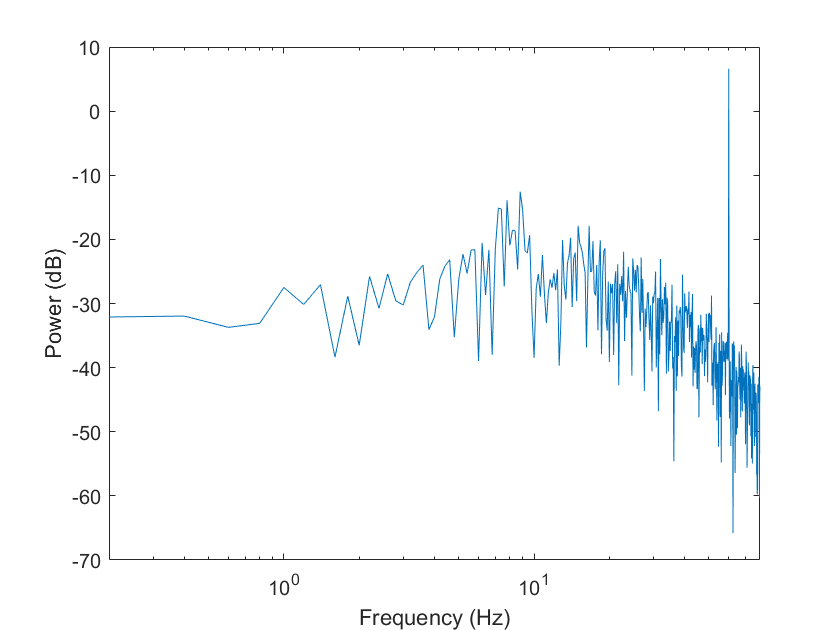

xlabel('Frequency (Hz)');
ylabel('Power (dB)');

I can see that there may be some signal at around 10-20 Hz since the power in dB is significantly higher than at any other frequencies than the signal at 60 Hz.

## Part 2: Removing electric outlet noise

- We can first plot the Fourier coefficients between -80 and 80 Hz:

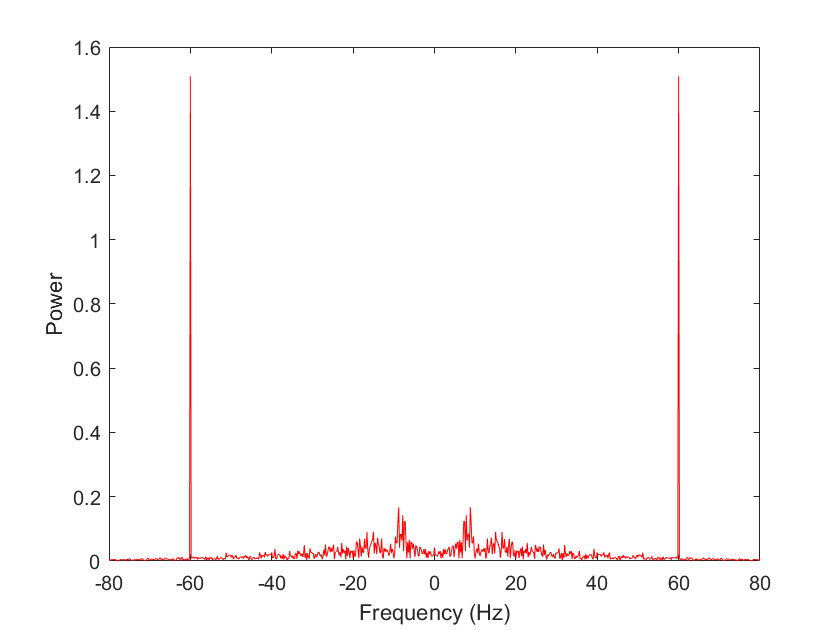

plot(freqvec, abs(FFTEP), 'r');
xlim([-80 80]);
xlabel('Frequency (Hz)');
ylabel('Power');

It seems that once we are above a magnitude of 0.2, the only Fourier coefficients with such a magnitude

is the noise at 60 Hz, thus we can filter around 0.15.

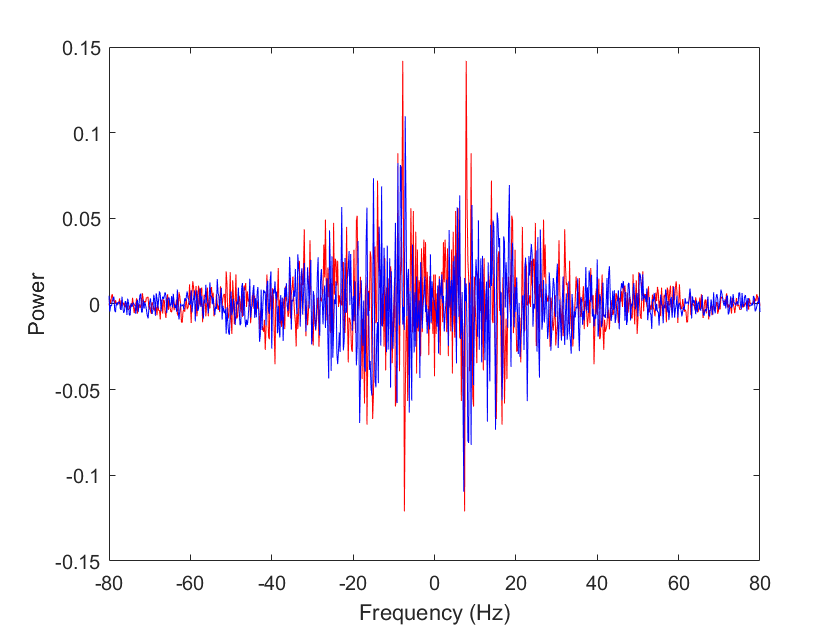

filteredFFT = FFTEP(:,:);
signallength = length(filteredFFT);
for i = 1:signallength
    if abs(filteredFFT(1,i)) > 0.15 %For all elements greater than 0.15
        filteredFFT(1,i) = 0; %Set the element to 0 instead
    end
end
figure;
%We plot these to visually check that we filtered out the 60 Hz noise
plot(freqvec,real(filteredFFT),'r');
hold on;
plot(freqvec,imag(filteredFFT),'b');
hold off;
xlim([-80 80]);
xlabel('Frequency (Hz)');
ylabel('Power');

2. Now we can recover our original signal:

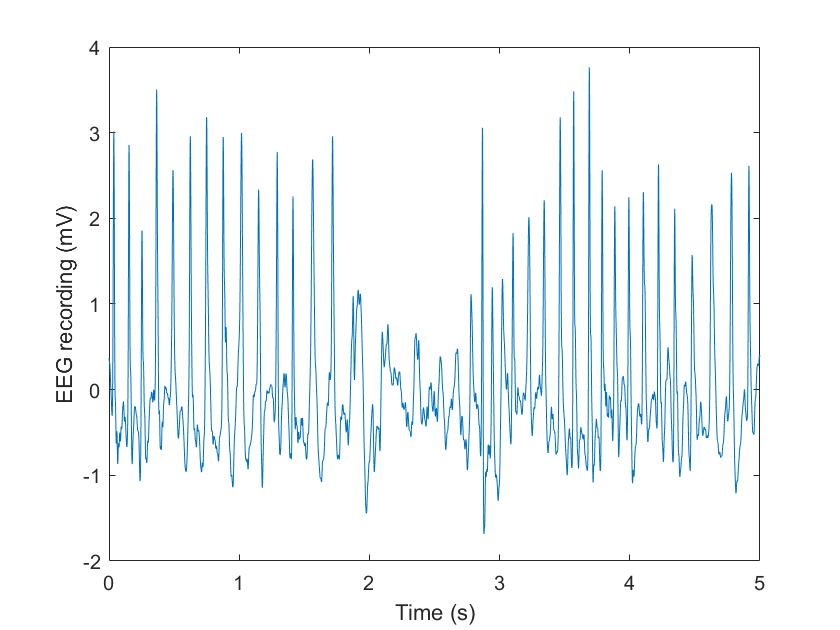

beforesignal = circshift(filteredFFT,[0,signallength/2]); %shift the signal back
recoveredsignal = ifft(beforesignal)*eplength; %take inverse FFt and normalize
figure;
plot(time,recoveredsignal);
xlabel('Time (s)');
ylabel('EEG recording (mV)');

3. We can make the periodogram below:

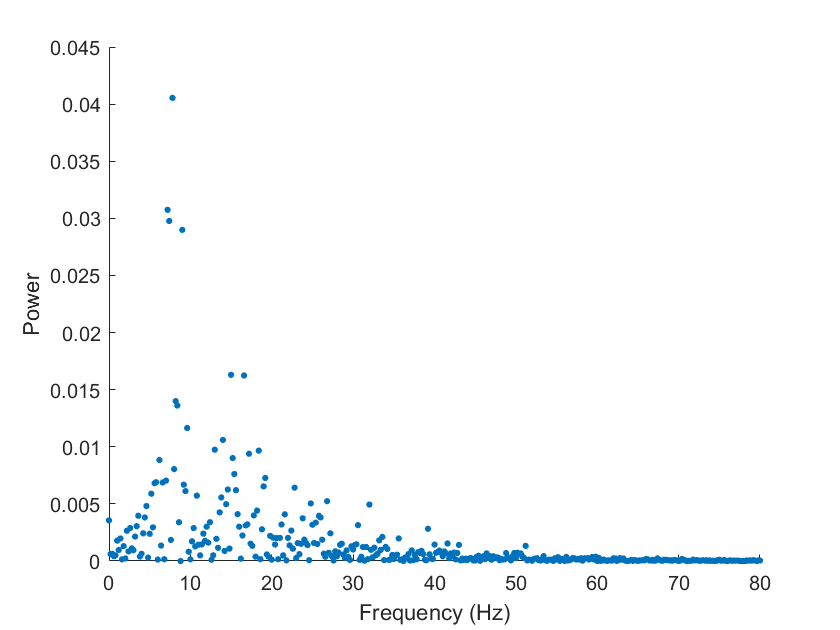

recoveredlength = length(recoveredsignal);
shiftedrecover =circshift(recoveredsignal,[0,recoveredlength/2]);      
fftrec =fft(shiftedrecover, recoveredlength)/recoveredlength;           
FFTREC =circshift(fftrec,[0,recoveredlength/2]);          
powerrec = 2*abs(FFTREC).^2;
figure;
scatter(freqvec,powerrec,10,'filled');
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel(['Power']);

4. We can put a zero padding factor below:

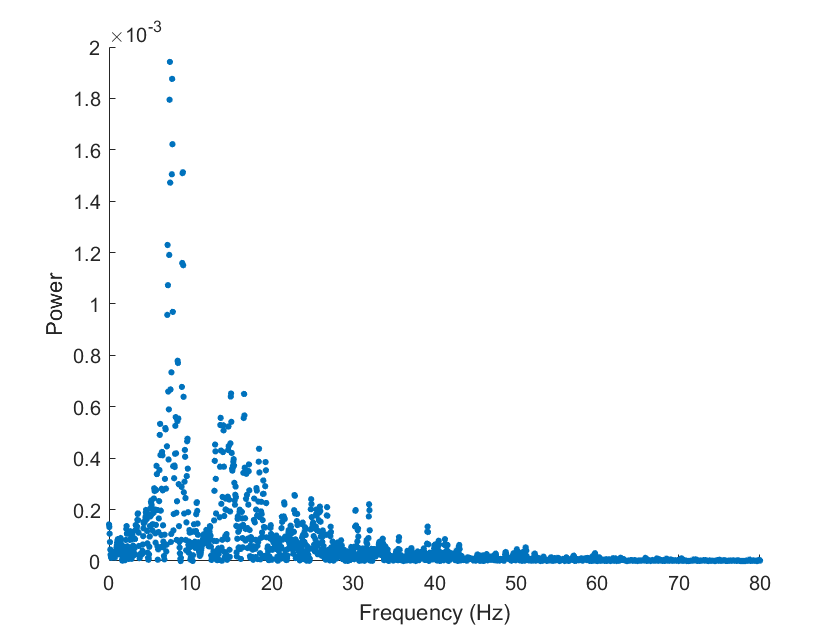

zeropadding = 5; %zero padding factor
newsignal(1,1:zeropadding*5000) = 0;
lowerbound = ((zeropadding/2)-0.5)*5000; 
upperbound = ((zeropadding/2)+0.5)*5000;
newsignal(1,lowerbound:upperbound-1) = recoveredsignal(1,1:5000);%middle of signal is the same
newrecoveredlength = length(recoveredsignal)*(zeropadding); %length of the vector
shiftednewrecover =circshift(newsignal,[0,newrecoveredlength/2]); %shift the signal     
fftnewrec =fft(shiftednewrecover, newrecoveredlength)/newrecoveredlength;%take normalized FFT           
FFTNEWREC =circshift(fftnewrec,[0,newrecoveredlength/2]);%shift the FFT back
powernewsig = 2*abs(FFTNEWREC).^2;%take power of the FFt
newfreqstep = 1000/newrecoveredlength;
newfreqvec = newfreqstep*[-(newrecoveredlength/2):(newrecoveredlength/2)-1]; 
figure;
scatter(newfreqvec,powernewsig, 10, 'filled');
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power');

The effect of zero-padding is that the signal has higher resolution than previously and looks overall less jagged. We can see that in that there are many more points in the spectrogram but the overall shape is the same.

## Part 3: Multi-taper spectra and spectrograms on the filtered data

- To look at these spectra, we can use the Wspec function. Our input data is the "recoveredsignal" variable above. The time-bandwidth product is 1.5, 2, and 5. The sampling rate is 1 kHz or 1000 Hz. The length of the short time window is 1 second.

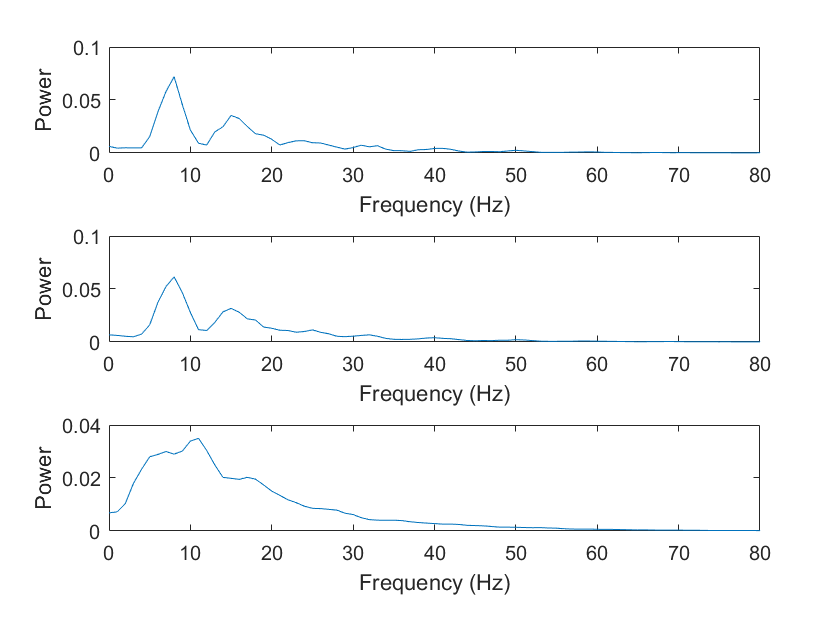

[spectra,frequencyvec] = WSpec(recoveredsignal,1.5,1,0,1000);
[spectra2,frequencyvec2] = WSpec(recoveredsignal,2,1,0,1000);
[spectra3,frequencyvec3] = WSpec(recoveredsignal,5,1,0,1000);
ax = [];
ax(1) = subplot(3,1,1);
plot(frequencyvec,spectra);
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power');
ax(2) = subplot(3,1,2);
plot(frequencyvec2,spectra2);
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power');
ax(3) = subplot(3,1,3);
plot(frequencyvec3,spectra3);
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power');
hold off

2. Now we redo this analysis except keeping our zero pad factor at 5, thus theoretically achieving more smoothed curve

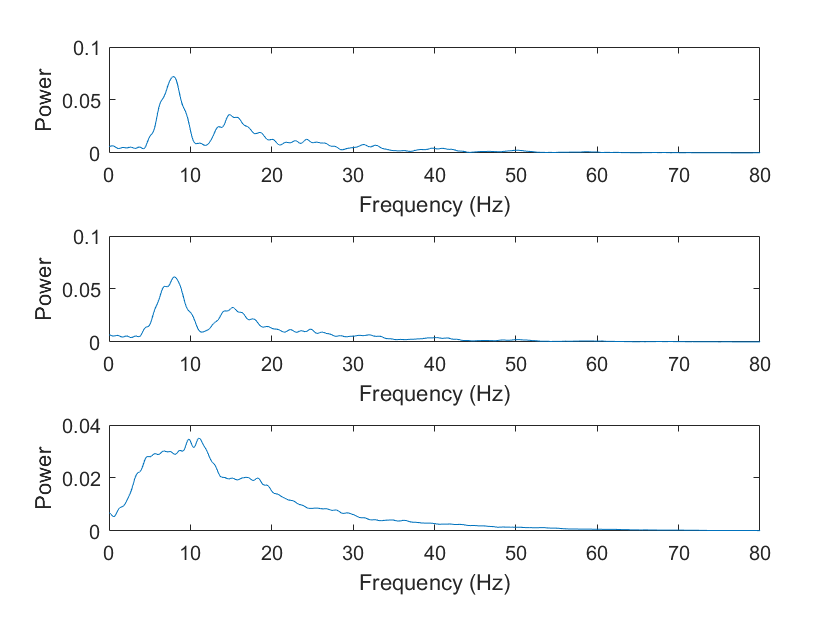

[spectra4,frequencyvec4] = WSpec(recoveredsignal,1.5,1,5,1000);
[spectra5,frequencyvec5] = WSpec(recoveredsignal,2,1,5,1000);
[spectra6,frequencyvec6] = WSpec(recoveredsignal,5,1,5,1000);
subplot(3,1,1);
plot(frequencyvec4,spectra4);
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power');
subplot(3,1,2);
plot(frequencyvec5,spectra5);
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power');
subplot(3,1,3);
plot(frequencyvec6,spectra6);
xlim([0 80]);
xlabel('Frequency (Hz)');
ylabel('Power');
hold off

I prefer the last set of tapers which uses a P of 1.5 since there is more differentiation and more obvious peaks at the two dominant frequencies of ~10 Hz and ~15 Hz. The multi taper results show similar results to the periodogram in that there is a high bump at a little less than 10 Hz and a smaller bump at around 15 Hz. However, what I find interesting is that based on the P value, we can smooth this curve out and have it reflect different  peak frequencies. I think that the periodogram is more informative. 

4. We can make the spectrogram as below:

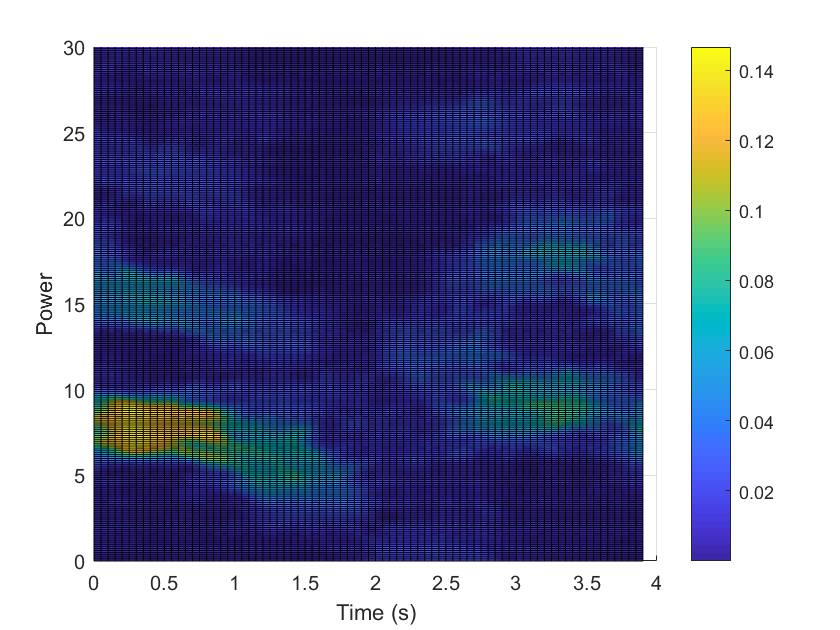

[specgram,specgramfrequencyvec,timevec] = WSpecgram(recoveredsignal,2,1,0.05,5,1000);
figure;
surf(timevec,specgramfrequencyvec,specgram); %Create a surface plot of the spectrogram
view(0,90);
xlabel('Time (s)');
h = colorbar;
ylabel('Frequency')
ylim([0 30]);

Rhythmic activity begins at the beginning of the time signal, stops at around 1.5 seconds, and then begins again at 3 seconds.

## Part 4: Comparison to normal data

- We can plot the normal EEG data below:

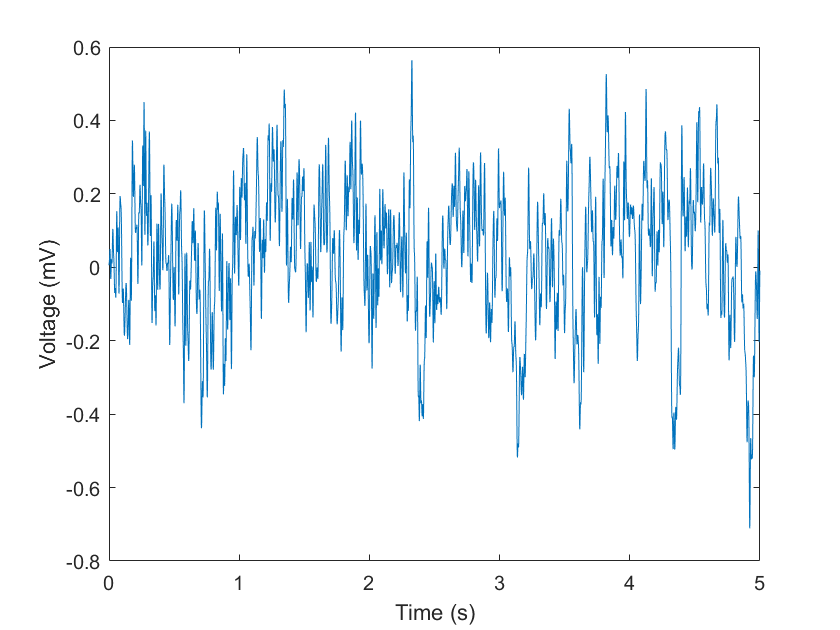

time = 0:.001:4.999;
figure;
plot(time,normal);
xlabel('Time (s)');
ylabel('Voltage (mV)');

The voltage shows much less variation and also is more spaced out than in the epileptic recording. This shows that the brain of a normal person is much less active than that of an epileptic person.

2. We can plot the autocorrelation as shown below:

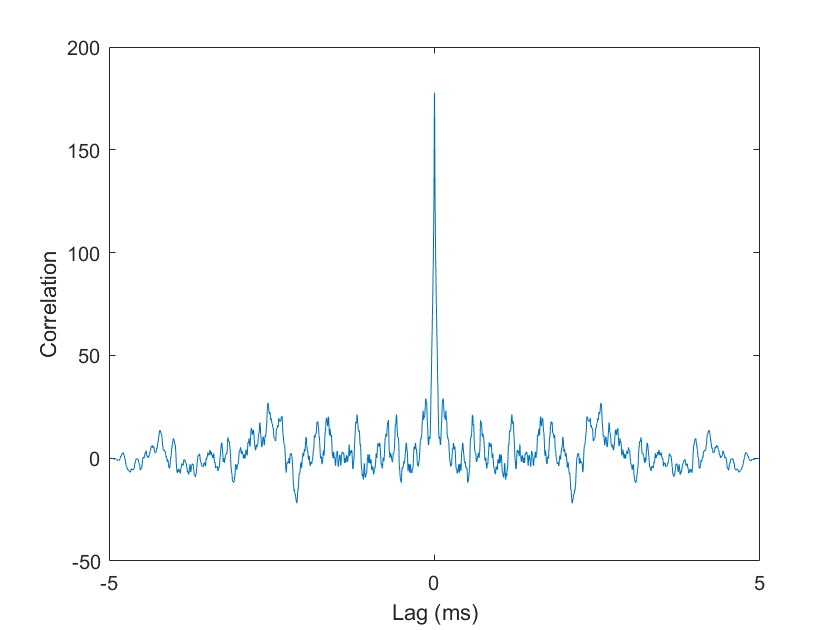

t = -4.999:.001:4.999;
normautocorr = xcorr(normal);
figure;
plot(t,normautocorr);
xlabel('Lag (ms)');
ylabel('Correlation');

For the most part it seems as though the signal does not have periodicity, as the autocorrelation strongly resembles the delta function, with slight amounts of noise.

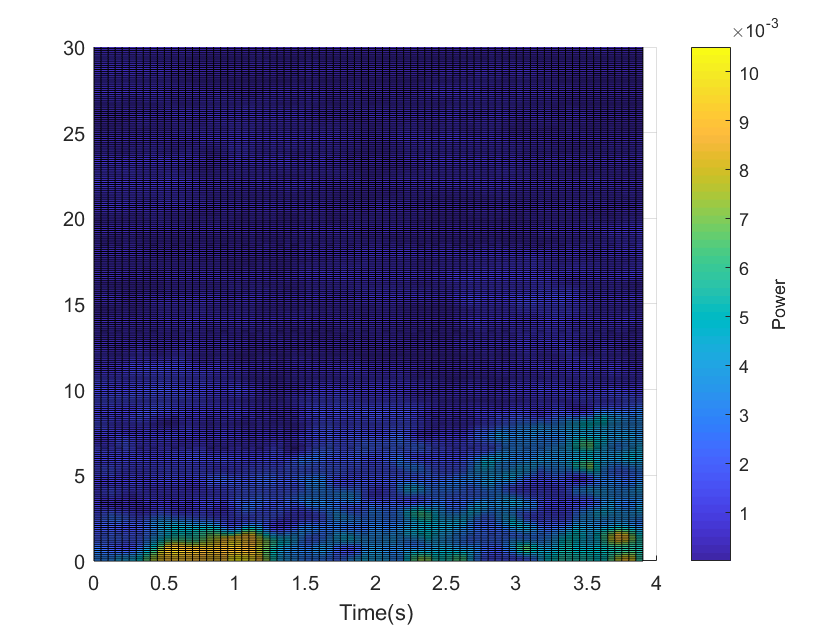

[normspecgram, normfreqvec, normtimevec] = WSpecgram(normal, 2,1,0.05,5,1000);
figure;
surf(normtimevec,normfreqvec,normspecgram);
view(0,90);
xlabel('Time(s)');
h = colorbar;
ylabel('Frequency');
ylim([0 30]);

The normal reading is a low frequency signal that occurs briefly at first and then a little bit more at the end of the 5 second period. It seems as though the epileptic reading shows higher frequency signals throughout the time period which reflects the greater amount of firing overall that we see.